# Problem 6.4: Evaluation and Discussion of Kalman Filters on Linear & Nonlinear Models

MPC Exam 2026 - Modified Four Tank System Evaluates the offset-free Kalman Filters (from Problem 4 and Problem 5) on both their respective Linear Plants and the true Nonlinear Plant.

clear; clc; close all;

% =========================================================================
% 1. Physical Parameters and Steady-State Operating Point (Exam 2026)
% =========================================================================
a      = 1.2272 * ones(4, 1);       % Pipe cross-sectional areas [cm^2]
A_tank = 380.1327 * ones(4, 1);     % Tank cross-sectional areas [cm^2]
gamma  = [0.6; 0.7];                % Valve positions for Exam 2026 [-]
g      = 981;                       % Gravitational acceleration [cm/s^2]
rho    = 1.0;                       % Water density [g/cm^3]
p      = [a; A_tank; gamma; g; rho];

% Nominal inputs and unmeasured disturbances
us   = [300; 300];                  % Nominal pump flows F1, F2 [cm^3/s]
d_s  = [175; 175];                  % Nominal unmeasured flows F3, F4 [cm^3/s]

% Wrapper handles both 4-arg and 5-arg definitions of FourTankSystem
try
    xs = fsolve(@(x) FourTankSystem(0, x, us, d_s, p), 10000*ones(4,1), ...
                optimoptions('fsolve', 'Display', 'none'));
    ode_fun = @(t, x, u, d) FourTankSystem(t, x, u, d, p);
catch
    xs = fsolve(@(x) FourTankSystem(0, x, us, p), 10000*ones(4,1), ...
                optimoptions('fsolve', 'Display', 'none'));
    ode_fun = @(t, x, u, d) FourTankSystem(t, x, u, p) + [0; 0; rho*(d(1)-d_s(1)); rho*(d(2)-d_s(2))];
end

hs = xs ./ (rho * A_tank);          % Steady-state levels of all 4 tanks [cm]
ys = hs(1:2);                       % Measured outputs: Tank 1 and Tank 2 [cm]
ny = 2;                             % Number of measured outputs
nu = 2;                             % Number of manipulated inputs
nd = 2;                             % Number of disturbance channels

fprintf('Steady-state masses xs [g]:   [%.2f, %.2f, %.2f, %.2f]\n', xs);

Steady-state masses xs [g]:   [25475.67, 32808.64, 9034.36, 11195.66]


fprintf('Steady-state levels ys [cm]:  [%.2f, %.2f]\n', ys);

Steady-state levels ys [cm]:  [67.02, 86.31]


Stationary estimator spectral radius: 0.987033



--- Problem 4 (Empirical + Output Disturbance Augmentation) ---


Tank 1 RMSE [cm]: linear static 0.891, linear dynamic 0.891 | nonlinear static 0.814, nonlinear dynamic 0.814
Tank 2 RMSE [cm]: linear static 0.868, linear dynamic 0.869 | nonlinear static 0.826, nonlinear dynamic 0.827


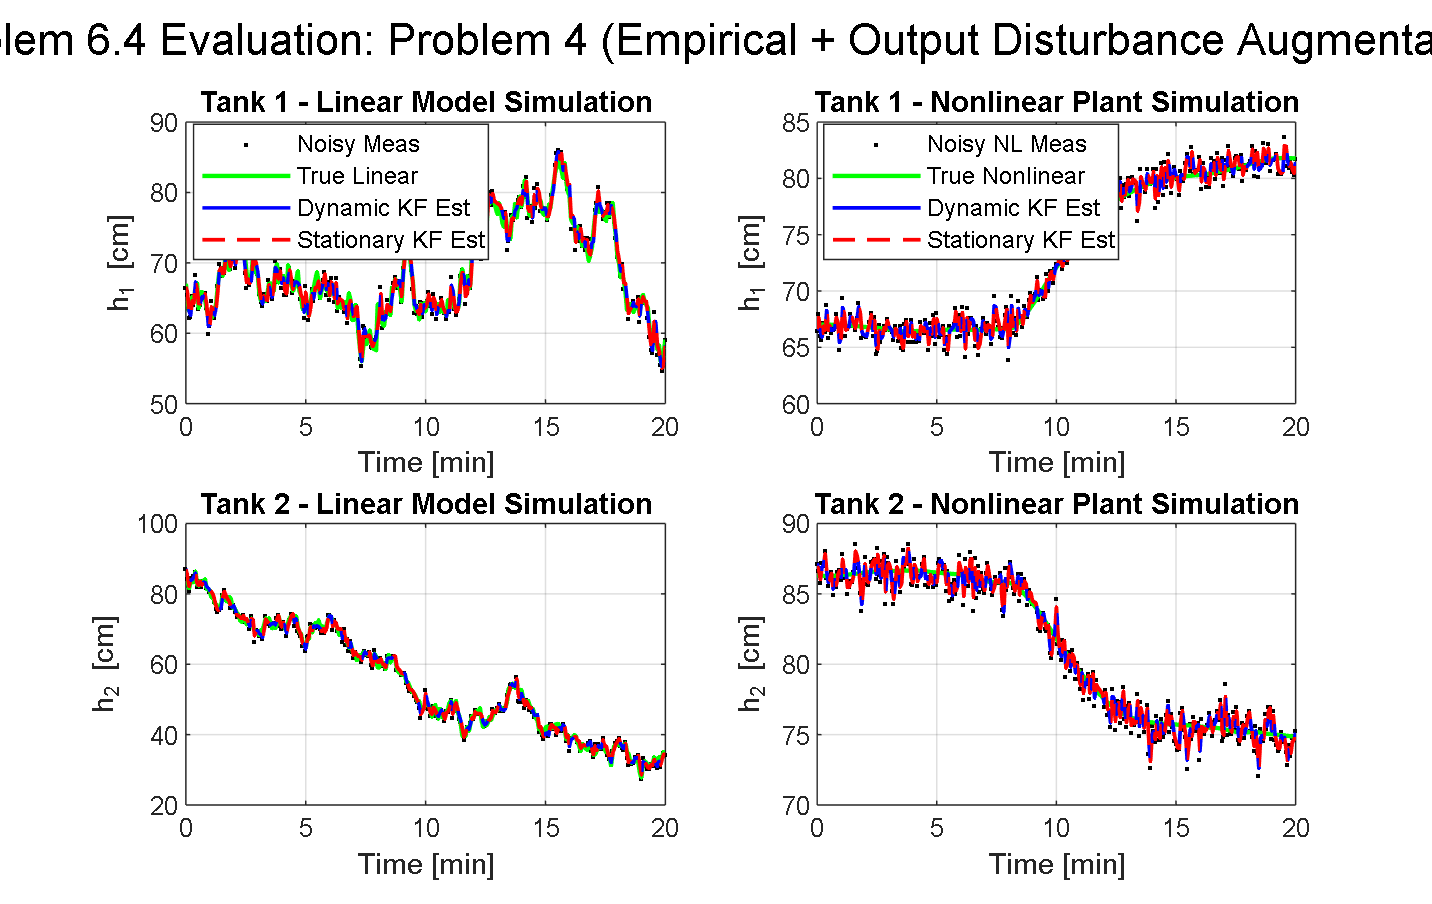

Stationary estimator spectral radius: 0.897547



--- Problem 5 (Physical Linearized Brownian Input Disturbance) ---


Tank 1 RMSE [cm]: linear static 0.570, linear dynamic 0.566 | nonlinear static 0.474, nonlinear dynamic 0.470
Tank 2 RMSE [cm]: linear static 0.592, linear dynamic 0.585 | nonlinear static 0.543, nonlinear dynamic 0.535


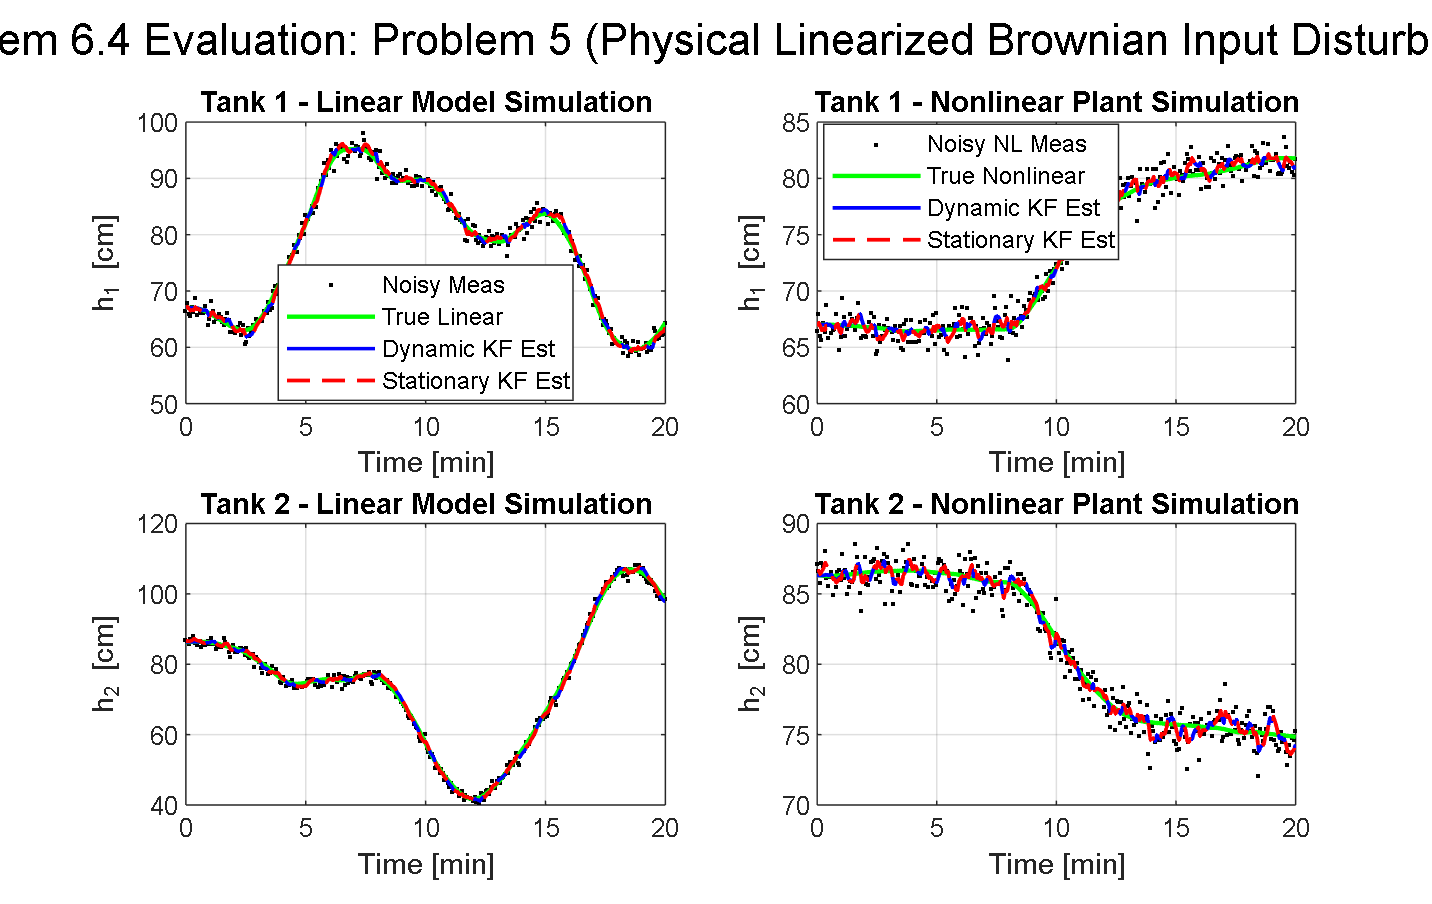


% =========================================================================
% 2. Load Discrete-Time Linear Models (Problem 4 & Problem 5)
% =========================================================================
% --- Load Problem 4 Model (Empirical Transfer Function Realization) ---
load('sysd_stochastic.mat'); 
A4_base = Ad_stochastic; 
B4_base = Bd_stochastic; 
C4_base = Cd_stochastic; 
D4_base = Dd_stochastic;
Ts      = Ts_markov;
nx4     = size(A4_base, 1);

% Augment Problem 4 with an exact output-disturbance random walk
A_m4 = [A4_base, zeros(nx4, ny); 
        zeros(ny, nx4), eye(ny)];
B_m4 = [B4_base; zeros(ny, nu)];
C_m4 = [C4_base, eye(ny)];
D_m4 = D4_base;
G_m4 = [B4_base, zeros(nx4, ny); 
        zeros(ny, nu), eye(ny)];

Q_x4 = diag([20^2, 20^2]);          % Input-referred process noise
Q_d4 = diag([1.5^2, 1.5^2]);        % Output disturbance random-walk tuning
Q_m4 = blkdiag(Q_x4, Q_d4);

% --- Load Problem 5 Model (First-Principles Brownian Model) ---
% Note: Brownian model ALREADY contains 2 disturbance states (nx = 6).
% Do NOT augment again to avoid redundant integrators and loss of observability.
load('model_prob5_discrete.mat');
A_m5 = A_d_Brownian;
% Keep the Brownian disturbance states as exact random walks.
% Do not change unit eigenvalues to 0.999: that would add leakage and
% can leave a steady-state offset under a permanent disturbance.
B_m5 = B_d_Brownian;
C_m5 = C_d_Brownian;
D_m5 = D_d_Brownian;
G_m5 = eye(size(A_m5, 1));          % Q_d_Brownian is already in state coordinates (Van Loan)
Q_m5 = Q_d_Brownian;

% Measurement noise covariance (1 cm standard deviation)
R = (1.0^2) * eye(ny);

% Group both models into a structure for clean iteration
models(1) = struct('Name', 'Problem 4 (Empirical + Output Disturbance Augmentation)', ...
                   'A', A_m4, 'B', B_m4, 'C', C_m4, 'D', D_m4, 'G', G_m4, 'Q', Q_m4);
models(2) = struct('Name', 'Problem 5 (Physical Linearized Brownian Input Disturbance)', ...
                   'A', A_m5, 'B', B_m5, 'C', C_m5, 'D', D_m5, 'G', G_m5, 'Q', Q_m5);

% =========================================================================
% 3. Stochastic Nonlinear Plant Simulation (Euler-Maruyama SDE)
% =========================================================================
rng(42);                            % Reproducible seed
tf    = 20 * 60;                    % 20 minutes simulation [s]
t     = (0:Ts:tf)';
N_sim = length(t);
time_min = t / 60;

% Manipulated input: kept at nominal us
u_abs = repmat(us, 1, N_sim);
u_dev = u_abs - repmat(us, 1, N_sim);

% Unmeasured disturbance F3, F4: includes a step change at t = 8 min
d_step = zeros(nd, N_sim);
step_idx = find(time_min >= 8, 1);
d_step(:, step_idx:end) = repmat([45; -35], 1, N_sim - step_idx + 1); % Step in F3, F4 [cm^3/s]
d_abs = repmat(d_s, 1, N_sim) + d_step;

% Sensor measurement noise v_k ~ N(0, R)
L_r    = chol(R, 'lower');
v_meas = L_r * randn(ny, N_sim);

% Euler-Maruyama parameters for continuous stochastic simulation
dt           = 0.1;                 % Integration micro-step [s]
steps_per_Ts = round(Ts / dt);
sigma_F      = 17.5;                % Continuous disturbance diffusion std
G_c_nl       = [0, 0; 0, 0; rho*sigma_F, 0; 0, rho*sigma_F]; % Enters Tanks 3 & 4

x_nl      = zeros(4, N_sim);
y_nl_true = zeros(ny, N_sim);
y_nl_meas = zeros(ny, N_sim);
x_nl(:, 1) = xs;                    % Start at steady state

for k = 1:N_sim-1
    % True physical levels of Tank 1 & 2 and noisy sensor reading
    h_k = x_nl(:, k) ./ (rho * A_tank);
    y_nl_true(:, k) = h_k(1:2);
    y_nl_meas(:, k) = y_nl_true(:, k) + v_meas(:, k);
    
    % Euler-Maruyama integration over [t_k, t_{k+1}]
    x_em = x_nl(:, k);
    for step = 1:steps_per_Ts
        dW    = sqrt(dt) * randn(nd, 1);
        dx_dt = ode_fun(0, x_em, u_abs(:, k), d_abs(:, k));
        x_em  = x_em + dx_dt * dt + G_c_nl * dW;
        x_em  = max(x_em, 0);       % Physical non-negativity of tank masses
    end
    x_nl(:, k+1) = x_em;
end
h_end = x_nl(:, N_sim) ./ (rho * A_tank);
y_nl_true(:, N_sim) = h_end(1:2);
y_nl_meas(:, N_sim) = y_nl_true(:, N_sim) + v_meas(:, N_sim);

% Nonlinear measurement in deviation variables for the linear Kalman Filters
y_nl_dev = y_nl_meas - repmat(ys, 1, N_sim);

% =========================================================================
% 4. Evaluate Static & Dynamic Kalman Filters on Linear & Nonlinear Models
% =========================================================================
for m = 1:length(models)
    A = models(m).A; B = models(m).B; C = models(m).C; 
    D = models(m).D; G = models(m).G; Q = models(m).Q;
    nx = size(A, 1);
    nw = size(G, 2);
    S  = zeros(nw, ny);
    
    % --- 4.1 Stationary Kalman Filter Design via DARE ---
    P_stat   = dare(A', C', G*Q*G', R, G*S);
    Re_stat  = C * P_stat * C' + R;
    Kfx_stat = (P_stat * C') / Re_stat;
    Kfw_stat = S / Re_stat;

    % Verify the stationary estimator error dynamics.
    A_est = A - (A * Kfx_stat + G * Kfw_stat) * C;
    rho_est = max(abs(eig(A_est)));
    fprintf('Stationary estimator spectral radius: %.6f\n', rho_est);
    if rho_est >= 1
        warning('Stationary estimator is not asymptotically stable for %s.', models(m).Name);
    end

    % --- 4.2 Simulate Linear Plant (with matching stochastic noise & step) ---
    x_lin_true = zeros(nx, N_sim);
    y_lin_true = zeros(ny, N_sim);
    y_lin_meas = zeros(ny, N_sim);
    
    % Factor the symmetric positive-semidefinite process covariance without
    % adding artificial noise to its zero-variance directions.
    Qsym = (Q + Q') / 2;
    [Vq, Dq] = eig(Qsym);
    lambda_q = real(diag(Dq));
    if min(lambda_q) < -1e-8
        error('Process covariance is not positive semidefinite for %s.', models(m).Name);
    end
    L_q = Vq * diag(sqrt(max(lambda_q, 0)));
    w_lin = L_q * randn(nw, N_sim);
    
    for k = 1:N_sim
        % Apply the step to the state at the declared sample, before its
        % measurement is generated. This avoids a one-sample timing delay.
        if k == step_idx
            if m == 1
                % Empirical augmented states are output offsets [cm]. Match the [5, -3] cm
                % magnitude used in Problem 6.3; this 6.4 step occurs at 8 min.
                x_lin_true(end-1:end, k) = x_lin_true(end-1:end, k) + [5.0; -3.0];
            else
                % Physical Brownian disturbance states represent F3 and F4 [cm^3/s].
                x_lin_true(5:6, k) = x_lin_true(5:6, k) + [45; -35];
            end
        end

        y_lin_true(:, k) = C * x_lin_true(:, k) + D * u_dev(:, k);
        y_lin_meas(:, k) = y_lin_true(:, k) + v_meas(:, k);

        if k < N_sim
            x_lin_true(:, k+1) = A * x_lin_true(:, k) ...
                               + B * u_dev(:, k) + G * w_lin(:, k);
        end
    end
    
    % --- 4.3 Filter Recursions on both linear and nonlinear plants ---
    x_hat_lin_stat = zeros(nx, N_sim);
    x_hat_lin_dyn  = zeros(nx, N_sim);
    x_hat_nl_stat  = zeros(nx, N_sim);
    x_hat_nl_dyn   = zeros(nx, N_sim);

    x_pred_lin_stat = zeros(nx, 1);
    x_pred_lin_dyn  = zeros(nx, 1);
    x_pred_nl_stat  = zeros(nx, 1);
    x_pred_nl_dyn   = zeros(nx, 1);
    P_pred_lin_dyn  = 100 * eye(nx);
    P_pred_nl_dyn   = 100 * eye(nx);

    for k = 1:N_sim
        % Stationary-gain KF on the matching linear model.
        [x_f_lin_s, x_p_lin_s, ~] = kalman_filter_stationary( ...
            y_lin_meas(:, k), u_dev(:, k), x_pred_lin_stat, ...
            A, B, C, D, G, Kfx_stat, Kfw_stat);
        x_hat_lin_stat(:, k) = x_f_lin_s;
        x_pred_lin_stat = x_p_lin_s;

        % Time-varying KF on the matching linear model.
        [x_f_lin_d, ~, x_p_lin_d, P_p_lin_d] = kalman_filter_time_variant( ...
            y_lin_meas(:, k), u_dev(:, k), x_pred_lin_dyn, P_pred_lin_dyn, ...
            A, B, C, D, G, Q, R, S);
        x_hat_lin_dyn(:, k) = x_f_lin_d;
        x_pred_lin_dyn = x_p_lin_d;
        P_pred_lin_dyn = P_p_lin_d;

        % Stationary-gain KF on the nonlinear plant measurements.
        [x_f_nl_s, x_p_nl_s, ~] = kalman_filter_stationary( ...
            y_nl_dev(:, k), u_dev(:, k), x_pred_nl_stat, ...
            A, B, C, D, G, Kfx_stat, Kfw_stat);
        x_hat_nl_stat(:, k) = x_f_nl_s;
        x_pred_nl_stat = x_p_nl_s;

        % Time-varying KF on the nonlinear plant measurements.
        [x_f_nl_d, ~, x_p_nl_d, P_p_nl_d] = kalman_filter_time_variant( ...
            y_nl_dev(:, k), u_dev(:, k), x_pred_nl_dyn, P_pred_nl_dyn, ...
            A, B, C, D, G, Q, R, S);
        x_hat_nl_dyn(:, k) = x_f_nl_d;
        x_pred_nl_dyn = x_p_nl_d;
        P_pred_nl_dyn = P_p_nl_d;
    end

    % Reconstruct absolute output estimates [cm].
    y_hat_lin_stat_abs = C * x_hat_lin_stat + repmat(ys, 1, N_sim);
    y_hat_lin_dyn_abs  = C * x_hat_lin_dyn  + repmat(ys, 1, N_sim);
    y_true_lin_abs     = y_lin_true         + repmat(ys, 1, N_sim);
    y_meas_lin_abs     = y_lin_meas         + repmat(ys, 1, N_sim);

    y_hat_nl_stat_abs = C * x_hat_nl_stat + repmat(ys, 1, N_sim);
    y_hat_nl_dyn_abs  = C * x_hat_nl_dyn  + repmat(ys, 1, N_sim);

    % Report both filters on both plants, using noise-free truth for RMSE.
    rmse_lin_stat = sqrt(mean((y_true_lin_abs - y_hat_lin_stat_abs).^2, 2));
    rmse_lin_dyn  = sqrt(mean((y_true_lin_abs - y_hat_lin_dyn_abs).^2, 2));
    rmse_nl_stat  = sqrt(mean((y_nl_true - y_hat_nl_stat_abs).^2, 2));
    rmse_nl_dyn   = sqrt(mean((y_nl_true - y_hat_nl_dyn_abs).^2, 2));

    fprintf('\n--- %s ---\n', models(m).Name);
    for i = 1:ny
        fprintf(['Tank %d RMSE [cm]: linear static %.3f, linear dynamic %.3f | ', ...
                 'nonlinear static %.3f, nonlinear dynamic %.3f\n'], ...
            i, rmse_lin_stat(i), rmse_lin_dyn(i), rmse_nl_stat(i), rmse_nl_dyn(i));
    end

    % --- 4.4 Plotting Comparison: Linear vs Nonlinear Simulation ---
    figure('Name', sprintf('Problem 6.4 - %s', models(m).Name), 'NumberTitle', 'off', 'Position', [100, 100, 950, 600]);
    for i = 1:ny
        % Left column: Filter on Linear Model
        subplot(ny, 2, 2*(i-1) + 1);
        plot(time_min, y_meas_lin_abs(i, :), 'k.', 'MarkerSize', 4, 'DisplayName', 'Noisy Meas'); hold on;
        plot(time_min, y_true_lin_abs(i, :), 'g-', 'LineWidth', 1.5, 'DisplayName', 'True Linear');
        plot(time_min, y_hat_lin_dyn_abs(i, :), 'b-', 'LineWidth', 1.2, 'DisplayName', 'Dynamic KF Est'); hold on;
        plot(time_min, y_hat_lin_stat_abs(i, :), 'r--', 'LineWidth', 1.3, 'DisplayName', 'Stationary KF Est');
        ylabel(sprintf('h_%d [cm]', i));
        xlabel('Time [min]');
        title(sprintf('Tank %d - Linear Model Simulation', i));
        grid on;
        if i == 1, legend('Location', 'best'); end
        
        % Right column: Filter on Nonlinear Model
        subplot(ny, 2, 2*(i-1) + 2);
        plot(time_min, y_nl_meas(i, :), 'k.', 'MarkerSize', 4, 'DisplayName', 'Noisy NL Meas'); hold on;
        plot(time_min, y_nl_true(i, :), 'g-', 'LineWidth', 1.5, 'DisplayName', 'True Nonlinear');
        plot(time_min, y_hat_nl_dyn_abs(i, :), 'b-', 'LineWidth', 1.3, 'DisplayName', 'Dynamic KF Est');
        plot(time_min, y_hat_nl_stat_abs(i, :), 'r--', 'LineWidth', 1.3, 'DisplayName', 'Stationary KF Est');
        ylabel(sprintf('h_%d [cm]', i));
        xlabel('Time [min]');
        title(sprintf('Tank %d - Nonlinear Plant Simulation', i));
        grid on;
        if i == 1, legend('Location', 'best'); end
    end
    sgtitle(['Problem 6.4 Evaluation: ', models(m).Name]);
end

## ========================================================================

5. Explicit Discussion of Disturbance Models (Required by Problem 6.4) ========================================================================= 1. Disturbance Models in Problem 4 (Empirical Realization): Because the state-space realization from Problem 4 (obtained via Markov parameters and SVD/Hankel matrices) consists of abstract mathematical states with no direct physical meaning, physical inflow disturbances (F3, F4) cannot be mapped directly to Tank 3 and Tank 4 masses. - For zero-mean noise (6.2), process noise is assumed to enter through the manipulated input channels (G = B_d). - For step disturbances (6.3 & 6.4), an Output Disturbance Model is used by augmenting the state vector with integrating disturbance states d_k acting directly on the measured outputs: d_{k+1} = d_k + w_{d,k} and y_k = C*x_k + d_k + v_k. Check observability of the resulting augmented pair with rank(obsv(A_aug,C_aug)); adding one disturbance per output does not, by itself, guarantee observability. The random-walk model allows the estimator to absorb persistent output offsets.

2. Disturbance Models in Problem 5 (Physical Linearized Models): The state-space models in Problem 5 retain physical tank masses as states (x_1..x_4) and explicitly include the disturbance input matrix E_c (mapping F3, F4 into Tanks 3 & 4). - In the Brownian model, two random-walk disturbance states (dd_t = sigma_B * dw_t) are already embedded in the 6-state vector, and exact discrete noise covariance Q_d is computed via Van Loan's matrix exponential method. Because these states act as internal input integrators, the Brownian Kalman filter tracks unmeasured step disturbances in F3 and F4 naturally without any additional state augmentation. Keep their transition eigenvalues at one; replacing them with 0.999 introduces leakage and may cause a steady-state offset under a permanent step. - In the Ornstein-Uhlenbeck (OU) model, disturbances are modeled as mean-reverting processes with finite correlation time (tau_F = 40 s), which is optimal for colored zero-mean fluctuations (6.2) but exhibits a small steady-state bias under permanent step changes unless augmented.

3. Linear vs. Nonlinear Simulation Performance: When applied to the nonlinear plant (simulated rigorously via Euler-Maruyama SDE integration), both filters operate on deviation variables (y_dev = y_nl - y_s). Near the nominal operating point, linear and nonlinear estimates behave almost identically. During large step disturbances (t >= 8 min), nonlinearity in the Bernoulli outflow (sqrt(2*g*h)) introduces minor plant-model mismatch, which the integrating disturbance states absorb to maintain zero steady-state offset.